# 2021-01-04-sgRNA

run_id = 'max_thres';

input_path = 'D:\2021-01-04-sgRNA\sample1\';
gpu_block = [1024 1024 6 4 2];

useGPU = true;

curr_out_path = fullfile(input_path, 'output', run_id);

if ~exist(curr_out_path, 'dir')
    mkdir(curr_out_path)
end
            
sdata = new_STARMapDataset(input_path, 'useGPU', useGPU);
sdata.log = fopen(fullfile(curr_out_path, 'log.txt'), 'w');
sdata = sdata.LoadRawImages('output_class', "cell");
sdata.rawImages = im_cell2mat(sdata.rawImages);
% sdata = sdata.SwapChannels; % !!

% % Thresholding
curr_bw = (50 > sdata.rawImages) & (sdata.rawImages > 0);
sdata.rawImages(curr_bw) = 0;

% Preprocessing
% sdata = sdata.HistEqualize('Method', "inter_round");
% sdata = sdata.HistEqualize('Method', "intra_round");
% sdata = sdata.MorphoRecon('Method', "2d", 'radius', 3);

## Registration

dims = size(sdata.rawImages);

rd1_dapi = new_LoadMultipageTiff(fullfile(input_path, 'round1/ch05.tif'), 'uint8', 'uint8', false); 
rd1_dapi = max(rd1_dapi, [], 3);
rd1_dapi = rd1_dapi(1:dims(1), 1:dims(2));
rd2_dapi = new_LoadMultipageTiff(fullfile(input_path, 'round2/ch05.tif'), 'uint8', 'uint8', false); 
rd2_dapi = max(rd2_dapi, [], 3);
rd2_dapi = rd2_dapi(1:dims(1), 1:dims(2));

% fix = gpuArray(rd1_dapi);
% move = gpuArray(rd2_dapi);

fix = rd1_dapi;
move = rd2_dapi;

[params, ~] = DFTRegister2D(fix, move, false);
params.shifts(3) = 0;
% params.diffphase = gather(params.diffphase);
fprintf(sprintf('Shifted by %s\n', num2str(params.shifts)));


for c=1:4
    tic;
    curr_reg = DFTApply3D(sdata.rawImages(:,:,:,c,2), params, false);
    sdata.rawImages(:,:,:,c,2) = uint8(curr_reg);
    fprintf(sprintf('[time = %.2f s]\n', toc));
end

reset(gpuDevice)

rd1 = max(sdata.rawImages(:,:,:,:,1), [], 4);
rd1 = max(rd1, [], 3);
rd2 = max(sdata.rawImages(:,:,:,:,2), [], 4);
rd2 = max(rd2, [], 3);

figure
imshowpair(rd1, rd2)

sdata.registeredImages = sdata.rawImages;

gpu_block = [2048 2048 6 4 2];
gpu_overlap = 0;
gb_idx = BlockTest(sdata.rawImages, gpu_block, gpu_overlap);
NgpuBlock = numel(gb_idx)

tile_goodSpots = [];
tile_goodReads = [];


upd = textprogressbar(NgpuBlock, 'updatestep', 1);
for i =1:NgpuBlock
    
    bdata_start = tic;
    gpu_idx = gb_idx{i}
    
    fprintf(sdata.log, sprintf("====Current Block: %d====\n", i));
    fprintf(sdata.log, sprintf("Index: %d - %d - %d - %d\n", gpu_idx));
    
    bdata = new_STARMapDataset(input_path, 'useGPU', useGPU);
    bdata.log = sdata.log;
    bdata = bdata.LoadDim(gpu_block);
    bdata.registeredImages = gpuArray(sdata.registeredImages(...
        gpu_idx(1,1):gpu_idx(1,2),...
        gpu_idx(2,1):gpu_idx(2,2),...
        :,:,:));
    
    bdata = bdata.LocalRegistration('Iterations', 50, 'AccumulatedFieldSmoothing', 1);
    
    % replace the old image 
    sdata.registeredImages(...
        gpu_idx(1,1):gpu_idx(1,2),...
        gpu_idx(2,1):gpu_idx(2,2),...
        :,:,:) = bdata.registeredImages;
    
    bdata = bdata.LoadCodebook;
    bdata = bdata.SpotFinding('Method', "barcode_test", 'ref_index', 1,  'qualityThreshold', 0.01, ...
            'volumeThreshold', 15, 'barcodeMethod', "iteration", 'showPlots', false);
%     bdata = bdata.ReadsExtraction('showPlots', false, 'voxelSize', [2 2 1]); 
%     bdata = bdata.ReadsFiltration('showPlots', false);
    
    block_offsets = [gpu_idx(2,1) - 1 gpu_idx(1,1) - 1 0]
    if size(bdata.allSpots, 1) ~= 0
        block_offsets = repmat(block_offsets, size(bdata.allSpots, 1), 1);
        bdata.allSpots = bdata.allSpots + int16(block_offsets);
    end
    
    % Update tile reads
    tile_goodSpots = [tile_goodSpots; bdata.allSpots];
    tile_goodReads = [tile_goodReads; bdata.allReads];

    
    fprintf(sprintf("====Block %d Finished [time=%02f]====", i, toc(bdata_start)));
    upd(i);
end

% Save registered image
output_dir = fullfile(curr_out_path, 'registered_image');
if ~exist(output_dir, 'dir')
   mkdir(output_dir);
end
new_SaveImg(output_dir, sdata.registeredImages);


% Save tile points 
save(fullfile(curr_out_path, strcat('goodPoints_max3d.mat')), 'tile_goodReads', 'tile_goodSpots');

reset(gpuDevice)

fclose(sdata.log);

plot_centroids(tile_goodSpots, rd1_dapi, 2)

rd1 = max(sdata.rawImages(:,:,:,:,1), [] ,4);
rd1 = max(rd1, [], 3);
plot_centroids(tile_goodSpots, rd1, 4)

## Spot finding refine

run_id = 'b100';

input_path = 'D:\2021-01-04-sgRNA\sample1_registered\';

useGPU = true;

curr_out_path = fullfile(input_path, 'output', run_id);

if ~exist(curr_out_path, 'dir')
    mkdir(curr_out_path)
end
            
sdata = new_STARMapDataset(input_path, 'useGPU', useGPU);

Pipeline Obj is generated...


sdata.log = fopen(fullfile(curr_out_path, 'log.txt'), 'w');
sdata = sdata.LoadRawImages('input_dim', [13108 9472 6 4 2]);

====Loading raw images====
Loading round 1...[time = 21.22 s]
Loading round 2...[time = 21.32 s]
Raw image as 5-D array



sdata.registeredImages = sdata.rawImages;

gpu_block = [3072 3072 6 4 2];
gpu_overlap = 0;
gb_idx = BlockTest(sdata.rawImages, gpu_block, gpu_overlap);
NgpuBlock = numel(gb_idx)

NgpuBlock = 20


tile_goodSpots = [];
tile_goodReads = [];


upd = textprogressbar(NgpuBlock, 'updatestep', 1);

Completed [                    ]   0% --:--:--

for i =1:NgpuBlock
    
    bdata_start = tic;
    gpu_idx = gb_idx{i}
    
    fprintf(sdata.log, sprintf("====Current Block: %d====\n", i));
    fprintf(sdata.log, sprintf("Index: %d - %d - %d - %d\n", gpu_idx));
    
    bdata = new_STARMapDataset(input_path, 'useGPU', useGPU);
    bdata.log = sdata.log;
    bdata = bdata.LoadDim(gpu_block);
%     bdata.registeredImages = gpuArray(sdata.registeredImages(...
%         gpu_idx(1,1):gpu_idx(1,2),...
%         gpu_idx(2,1):gpu_idx(2,2),...
%         :,:,:));
    
    bdata.registeredImages = sdata.registeredImages(...
        gpu_idx(1,1):gpu_idx(1,2),...
        gpu_idx(2,1):gpu_idx(2,2),...
        :,:,:);
    

    
    bdata = bdata.LoadCodebook;
    bdata = bdata.SpotFinding('Method', "barcode_test", 'ref_index', 1,  'qualityThreshold', 0.01, ...
            'volumeThreshold', 100, 'barcodeMethod', "iteration", 'showPlots', false);
%     bdata = bdata.ReadsExtraction('showPlots', false, 'voxelSize', [2 2 1]); 
%     bdata = bdata.ReadsFiltration('showPlots', false);
    
    block_offsets = [gpu_idx(2,1) - 1 gpu_idx(1,1) - 1 0]
    if size(bdata.allSpots, 1) ~= 0
        block_offsets = repmat(block_offsets, size(bdata.allSpots, 1), 1);
        bdata.allSpots = bdata.allSpots + int16(block_offsets);
    end
    
    % Update tile reads
    tile_goodSpots = [tile_goodSpots; bdata.allSpots];
    tile_goodReads = [tile_goodReads; bdata.allReads];

    
    fprintf(sprintf("====Block %d Finished [time=%02f]====", i, toc(bdata_start)));
    upd(i);
end

gpu_idx =            1        3072
           1        3072


Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.92, C: 194747[time = 9.45 s]
Get barcodes for Round 2....Q: 0.98, C: 644739[time = 9.24 s]
The global quality score threshold for barcode calling is: 0.02 
Iterate through clusters...[time = 52.93 s]
Number of spots found by barcode_test: 216
[time = 53.18 s]


block_offsets =      0     0     0


====Block 1 Finished [time=75.969164]====

Completed [=                   ]   5% 00:24:04

gpu_idx =            1        3072
        3073        6144


Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.97, C: 81176[time = 8.88 s]
Get barcodes for Round 2....Q: 0.98, C: 310749[time = 9.38 s]
The global quality score threshold for barcode calling is: 0.02 
Iterate through clusters...[time = 47.38 s]
Number of spots found by barcode_test: 83
[time = 47.65 s]


block_offsets =         3072           0           0


====Block 2 Finished [time=70.062015]====

Completed [==                  ]  10% 00:21:54

gpu_idx =            1        3072
        6145        9216


Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.97, C: 98558[time = 9.29 s]
Get barcodes for Round 2....Q: 0.98, C: 479593[time = 8.85 s]
The global quality score threshold for barcode calling is: 0.02 
Iterate through clusters...[time = 49.16 s]
Number of spots found by barcode_test: 64
[time = 49.44 s]


block_offsets =         6144           0           0


====Block 3 Finished [time=71.629222]====

Completed [===                 ]  15% 00:20:34

gpu_idx =            1        3072
        9217        9472


Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.98, C: 9687[time = 0.72 s]
Get barcodes for Round 2....Q: 0.98, C: 46352[time = 0.85 s]
The global quality score threshold for barcode calling is: 0.02 
Iterate through clusters...[time = 1.88 s]
Number of spots found by barcode_test: 7
[time = 1.91 s]


block_offsets =         9216           0           0


====Block 4 Finished [time=3.975335]====

Completed [====                ]  20% 00:14:47

gpu_idx =         3073        6144
           1        3072


Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.97, C: 267619[time = 9.39 s]
Get barcodes for Round 2....Q: 0.98, C: 989176[time = 9.08 s]
The global quality score threshold for barcode calling is: 0.02 
Iterate through clusters...[time = 49.21 s]
Number of spots found by barcode_test: 271
[time = 49.50 s]


block_offsets =            0        3072           0


====Block 5 Finished [time=72.240812]====

Completed [=====               ]  25% 00:14:42

gpu_idx =         3073        6144
        3073        6144


Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.93, C: 334746[time = 9.44 s]
Get barcodes for Round 2....Q: 0.98, C: 1277787[time = 9.04 s]
The global quality score threshold for barcode calling is: 0.02 
Iterate through clusters...[time = 49.09 s]
Number of spots found by barcode_test: 461
[time = 49.35 s]


block_offsets =         3072        3072           0


====Block 6 Finished [time=71.948594]====

Completed [======              ]  30% 00:14:14

gpu_idx =         3073        6144
        6145        9216


Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.94, C: 215652[time = 9.00 s]
Get barcodes for Round 2....Q: 0.98, C: 1124815[time = 9.57 s]
The global quality score threshold for barcode calling is: 0.02 
Iterate through clusters...[time = 47.79 s]
Number of spots found by barcode_test: 315
[time = 48.08 s]


block_offsets =         6144        3072           0


====Block 7 Finished [time=71.014781]====

Completed [=======             ]  35% 00:13:31

gpu_idx =         3073        6144
        9217        9472


Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.99, C: 15625[time = 0.76 s]
Get barcodes for Round 2....Q: 0.99, C: 100177[time = 0.82 s]
The global quality score threshold for barcode calling is: 0.02 
Iterate through clusters...[time = 1.83 s]
Number of spots found by barcode_test: 11
[time = 1.85 s]


block_offsets =         9216        3072           0


====Block 8 Finished [time=3.910782]====

Completed [========            ]  40% 00:11:01

gpu_idx =         6145        9216
           1        3072


Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.95, C: 382207[time = 9.04 s]
Get barcodes for Round 2....Q: 0.98, C: 1590862[time = 8.94 s]
The global quality score threshold for barcode calling is: 0.02 
Iterate through clusters...[time = 48.54 s]
Number of spots found by barcode_test: 345
[time = 48.81 s]


block_offsets =            0        6144           0


====Block 9 Finished [time=71.117577]====

Completed [=========           ]  45% 00:10:26

gpu_idx =         6145        9216
        3073        6144


Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.95, C: 337676[time = 9.23 s]
Get barcodes for Round 2....Q: 0.98, C: 1716381[time = 9.17 s]
The global quality score threshold for barcode calling is: 0.02 
Iterate through clusters...[time = 49.74 s]
Number of spots found by barcode_test: 328
[time = 50.00 s]


block_offsets =         3072        6144           0


====Block 10 Finished [time=72.533436]====

Completed [==========          ]  50% 00:09:44

gpu_idx =         6145        9216
        6145        9216


Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.95, C: 178414[time = 8.88 s]
Get barcodes for Round 2....Q: 0.97, C: 813218[time = 9.40 s]
The global quality score threshold for barcode calling is: 0.02 
Iterate through clusters...[time = 47.19 s]
Number of spots found by barcode_test: 148
[time = 47.46 s]


block_offsets =         6144        6144           0


====Block 11 Finished [time=69.873566]====

Completed [===========         ]  55% 00:08:55

gpu_idx =         6145        9216
        9217        9472


Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.99, C: 8952[time = 0.74 s]
Get barcodes for Round 2....Q: 0.99, C: 43524[time = 0.85 s]
The global quality score threshold for barcode calling is: 0.02 
Iterate through clusters...[time = 1.80 s]
Number of spots found by barcode_test: 3
[time = 1.82 s]


block_offsets =         9216        6144           0


====Block 12 Finished [time=3.916759]====

Completed [============        ]  60% 00:07:19

gpu_idx =         9217       12288
           1        3072


Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.96, C: 452068[time = 9.04 s]
Get barcodes for Round 2....Q: 0.98, C: 2188176[time = 9.11 s]
The global quality score threshold for barcode calling is: 0.02 
Iterate through clusters...[time = 45.88 s]
Number of spots found by barcode_test: 428
[time = 46.17 s]


block_offsets =            0        9216           0


====Block 13 Finished [time=68.446786]====

Completed [=============       ]  65% 00:06:31

gpu_idx =         9217       12288
        3073        6144


Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.94, C: 329873[time = 9.43 s]
Get barcodes for Round 2....Q: 0.97, C: 1528220[time = 9.07 s]
The global quality score threshold for barcode calling is: 0.02 
Iterate through clusters...[time = 48.24 s]
Number of spots found by barcode_test: 330
[time = 48.50 s]


block_offsets =         3072        9216           0


====Block 14 Finished [time=71.116021]====

Completed [==============      ]  70% 00:05:42

gpu_idx =         9217       12288
        6145        9216


Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.93, C: 122501[time = 9.05 s]
Get barcodes for Round 2....Q: 0.96, C: 474567[time = 9.10 s]
The global quality score threshold for barcode calling is: 0.02 
Iterate through clusters...[time = 48.93 s]
Number of spots found by barcode_test: 125
[time = 49.23 s]


block_offsets =         6144        9216           0


====Block 15 Finished [time=71.570430]====

Completed [===============     ]  75% 00:04:50

gpu_idx =         9217       12288
        9217        9472


Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.97, C: 1186[time = 0.88 s]
Get barcodes for Round 2....Q: 0.99, C: 6884[time = 0.86 s]
The global quality score threshold for barcode calling is: 0.02 
Iterate through clusters...[time = 1.83 s]
Number of spots found by barcode_test: 0
[time = 1.86 s]


block_offsets =         9216        9216           0


====Block 16 Finished [time=4.094262]====

Completed [================    ]  80% 00:03:38

gpu_idx =        12289       13108
           1        3072


Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.98, C: 50607[time = 2.64 s]
Get barcodes for Round 2....Q: 0.98, C: 425273[time = 2.58 s]
The global quality score threshold for barcode calling is: 0.02 
Iterate through clusters...[time = 7.28 s]
Number of spots found by barcode_test: 28
[time = 7.35 s]


block_offsets =            0       12288           0


====Block 17 Finished [time=13.811494]====

Completed [=================   ]  85% 00:02:37

gpu_idx =        12289       13108
        3073        6144


Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.98, C: 28145[time = 2.28 s]
Get barcodes for Round 2....Q: 0.98, C: 223639[time = 2.33 s]
The global quality score threshold for barcode calling is: 0.02 
Iterate through clusters...[time = 7.30 s]
Number of spots found by barcode_test: 13
[time = 7.38 s]


block_offsets =         3072       12288           0


====Block 18 Finished [time=13.156287]====

Completed [==================  ]  90% 00:01:40

gpu_idx =        12289       13108
        6145        9216


Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.93, C: 43484[time = 2.39 s]
Get barcodes for Round 2....Q: 0.98, C: 177436[time = 2.40 s]
The global quality score threshold for barcode calling is: 0.02 
Iterate through clusters...[time = 7.03 s]
Number of spots found by barcode_test: 62
[time = 7.10 s]


block_offsets =         6144       12288           0


====Block 19 Finished [time=13.075963]====

Completed [=================== ]  95% 00:00:48

gpu_idx =        12289       13108
        9217        9472


Pipeline Obj is generated...


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.98, C: 2971[time = 0.20 s]
Get barcodes for Round 2....Q: 0.97, C: 19649[time = 0.21 s]
The global quality score threshold for barcode calling is: 0.02 
Iterate through clusters...[time = 0.44 s]
Number of spots found by barcode_test: 2
[time = 0.45 s]


block_offsets =         9216       12288           0


====Block 20 Finished [time=1.016403]====

Completed [====================] Done. [915 seconds]




% Save tile points 
save(fullfile(curr_out_path, strcat('goodPoints_max3d.mat')), 'tile_goodReads', 'tile_goodSpots');

reset(gpuDevice)

fclose(sdata.log);

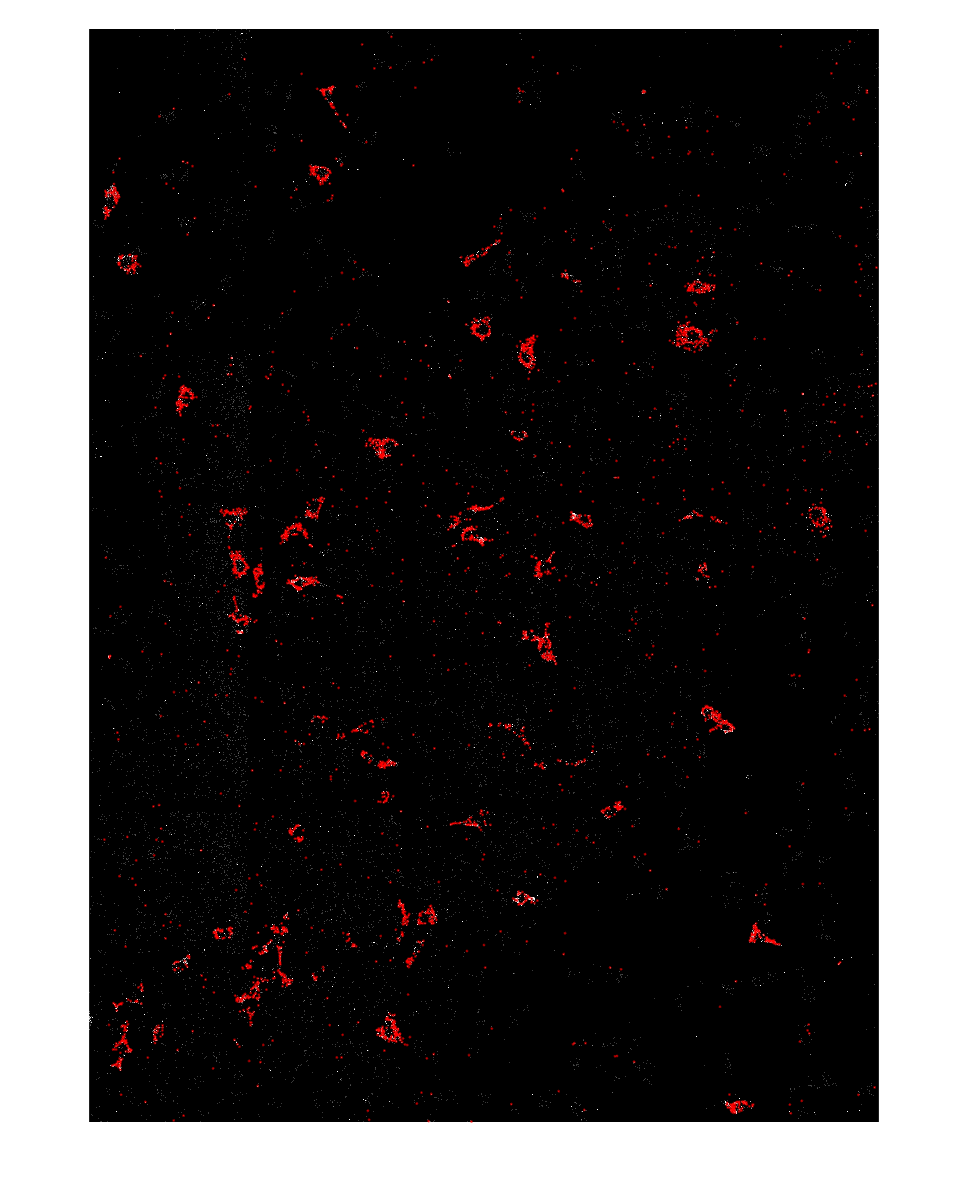


rd1 = max(sdata.rawImages(:,:,:,:,1), [] ,4);
rd1 = max(rd1, [], 3);
plot_centroids(tile_goodSpots, rd1, 4)